## Clear Workspace

clc
clearvars
close all

unit = 10^(-3);             %all units in mm

## Variables for the conical Antenna

r1 = 20*unit;               %Radius of the waveguide
r2 = 34*unit;               %Radius of the cone aperture
h1 = 39.2*unit;             %Length of the waveguide
h2 = 40*unit;               %Length of the cone attachment
h3 = 6.6*unit;              %height of the Probe inside the waveguide
Fw = 0.2*unit;              %width of the Probe inside the waveguide
Fo = 13.1*unit;             %Distance beetween bottomend of the waveguide an the probe
Material = metal("Aluminium")

Material =   metal with properties:

            Name: 'Aluminium'
    Conductivity: 37700000
       Thickness: 7.6200e-04

For more materials see catalog



freq = 10.489*10^(9);       %Frequency of interest

## Creation of the Antenna element

ant = hornConical(Radius=r1, ...
    ApertureRadius=r2, ...
    WaveguideHeight=h1, ...
    ConeHeight=h2, ...
    FeedHeight=h3, ...
    FeedWidth=Fw, ...
    FeedOffset=Fo, ...
    Conductor=Material)

ant =   hornConical with properties:

             Radius: 0.0200
    WaveguideHeight: 0.0392
         FeedHeight: 0.0066
          FeedWidth: 2.0000e-04
         FeedOffset: 0.0131
         ConeHeight: 0.0400
     ApertureRadius: 0.0340
          Conductor: [1×1 metal]
               Tilt: 0
           TiltAxis: [1 0 0]
               Load: [1×1 lumpedElement]


## Analysis of the Antenna

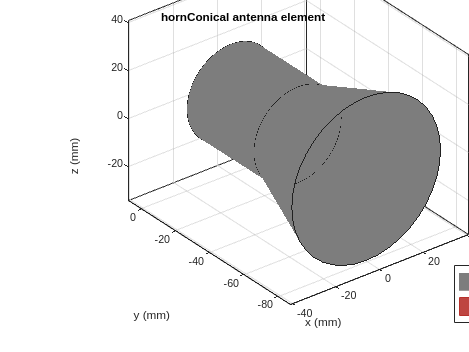

show(ant)           

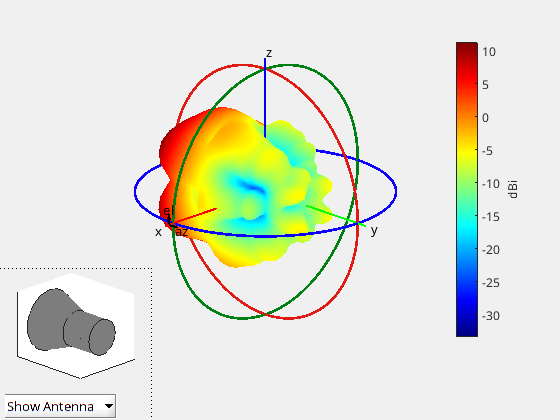

pattern(ant,freq)

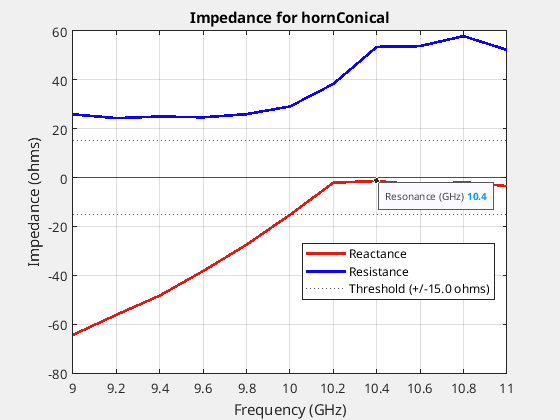

ans = 1.0400e+10

resonantFrequency(ant,9e9:200e6:11e9)

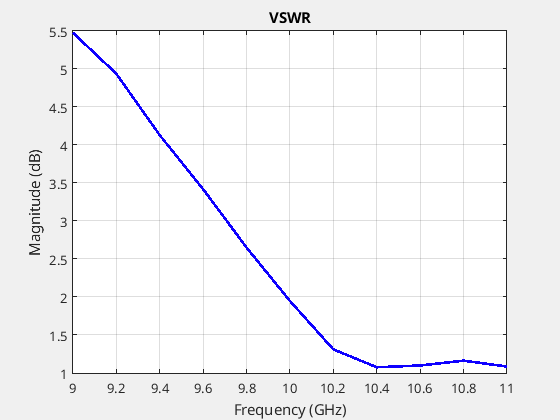

vswr(ant,9e9:200e6:11e9)

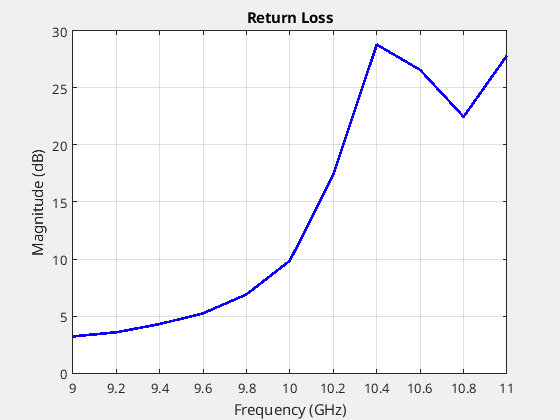

returnLoss(ant,9e9:200e6:11e9)